# Using freqz to plot frequency response

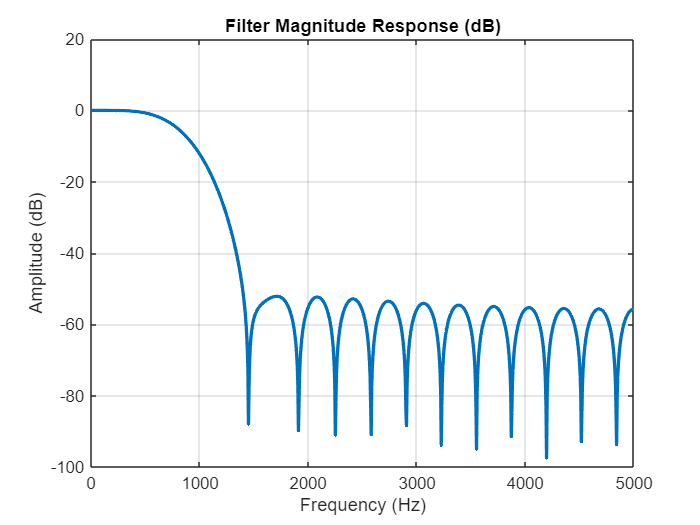

%

% Define the impulse response.  An FIR filter has all zeros and no poles so
% there are only coefficients in the numberato and no coefficients 
% in the denominator
%

b = [0.001692, 0.001768, 0.001462, -0.000000, -0.003349, -0.008518, -0.014026, -0.016897, -0.013328, 0.000000, 0.024432, 0.058241, 0.096474, 0.131929,...
0.157053, 0.166136, 0.157053, 0.131929, 0.096474, 0.058241, 0.024432, 0.000000, -0.013328, -0.016897, -0.014026, -0.008518, -0.003349, -0.000000,...
0.001462, 0.001768, 0.001692];  %  Numerator Coefficients

a = 1;  %  Denominator coefficient

%  Use the freqz command to compute the frequency response of the filter.
%  Use 1000 points

[h,w] = freqz(b, a, 1000);

%  Plot the magnitude in decibels of the frequency response assuming the
%  sampling rate is 10 kHz

freqSample = 10e3;  %  Sampling frequency
freqHz = w/(2*pi) * freqSample;  %  Conver the frequency sweep to absolute Hz
magdb = 20*log10(abs(h));  %  Compute the magnitude in decibels
phaseDeg = rad2deg(angle(h));


figure
plot(freqHz, magdb, 'LineWidth',2)
grid on
title('Filter Magnitude Response (dB)')
xlabel('Frequency (Hz)')
ylabel('Amplitude (dB)')

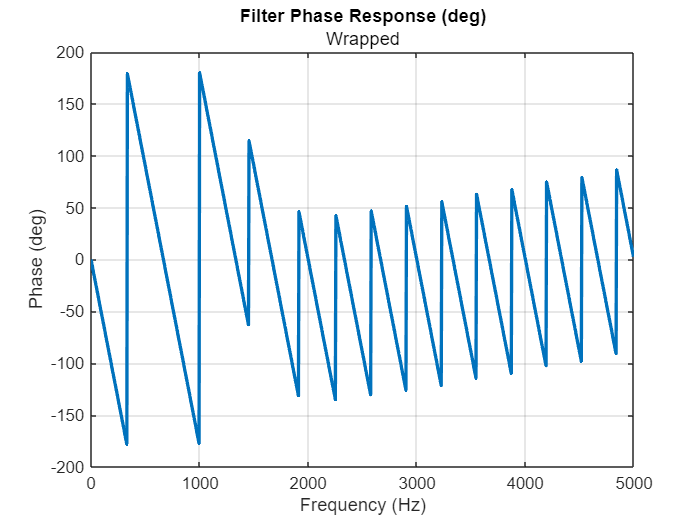


figure
plot(freqHz, phaseDeg, 'LineWidth',2)
grid on
title('Filter Phase Response (deg)','Wrapped')
xlabel('Frequency (Hz)')
ylabel('Phase (deg)')

# Using impz to plot the impulse response

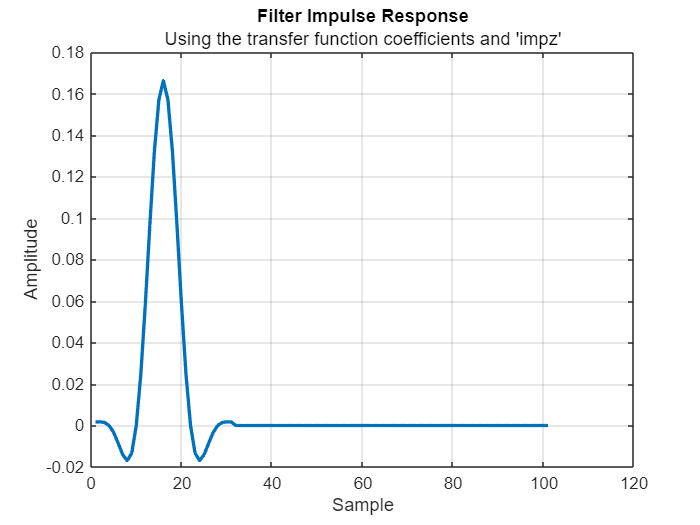

%  Find the impulse response from the transfer function coefficients for
%  the numerator and the denomenator.

impulseResponse = impz(b,a,101);


figure
plot(impulseResponse,'LineWidth',2)
grid on
title('Filter Impulse Response','Using the transfer function coefficients and ''impz''')
xlabel('Sample');
ylabel('Amplitude')

# Using stepz to plot the step response

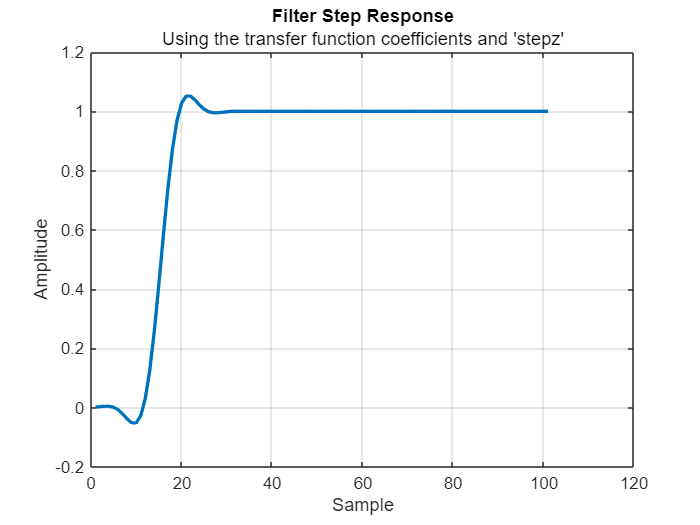

%  Find the step response from the transfer function coefficients for
%  the numerator and the denomenator.

stepResponse = stepz(b,a,101);


figure
plot(stepResponse,'LineWidth',2)
grid on
title('Filter Step Response','Using the transfer function coefficients and ''stepz''')
xlabel('Sample');
ylabel('Amplitude')